## Assignment 1: 180437U

**1.Obtain the plot of the given signal using matlab (for 10 ms duration).**

To plot the graphs, I have predefined the function **graph(t,y, name,c)**.

Inputs:

- t: time axis

- y: function(a vector) that needs to be plotted

- name: title of the graph

- c: boolean value. True to plot continuous value. False to plot discrete values

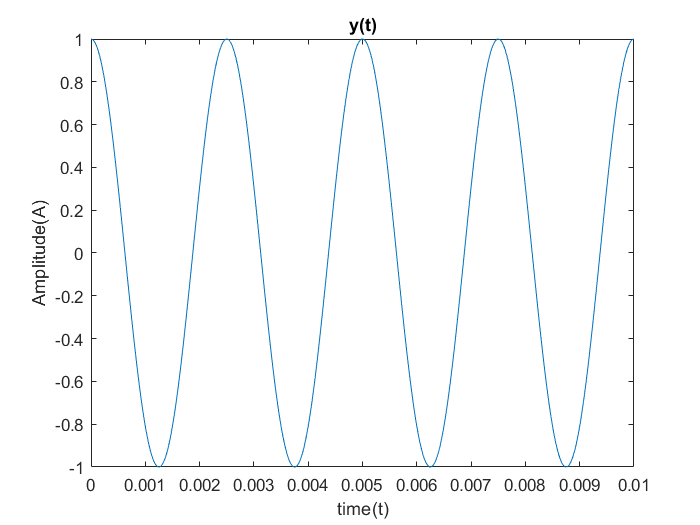

%plotting the y(t) function
f=400;                  %frequency
t=0:1e-6:0.01;          %creating the time axis
y=cos(2*pi*f*t);        %creating the vector
graph(t,y,"y(t)",true); %plotting the graph

**2. Find the Nyquist sampling frequency (fnq).**

- Since our signal is a single cosine component, the frequency domain has only one component at $\omega$ = 2$\pi f$, Where f=400$H_z$.

- So $f_{\mathrm{max}}$=400.

- According to Nyquist theorem, to avoid frequency domain aliasing, fs should be greater than or equal to 2fmax.

- $f_s$$\ge$2$f_{\mathrm{max}}$

- $f_{\mathrm{nq}}$=2$f_{\mathrm{max}}$=800$H_z$

**3. Sample the signal (use ideal sampling) at Nyquist sampling rate (fnq) and plot the sampled signal using matlab.**

To sample the signal I'm using impulse train.

$y_{\mathrm{sampled}} \left(t\right)$=$y\left(t\right)\times \delta_{\mathrm{Ts}} \left(t\right)$

Where $\delta_{\textrm{Ts}} \left(t\right)$ is train of periodic shifted impulses with a period $\mathrm{Ts}$. Here $\mathrm{Ts}$=1/$f_s$ and $f_s$=$f_{\textrm{nq}}$.

First I have constructed the impulse train as below. Here I'm using the predefined function **deltap(t,Ts)**, which outputs a vector of same size of t, with a periodic impulse train having a period Ts.

**deltap(t,Ts)**

Parameters,

- t: time axis vector

- Ts: sampling period

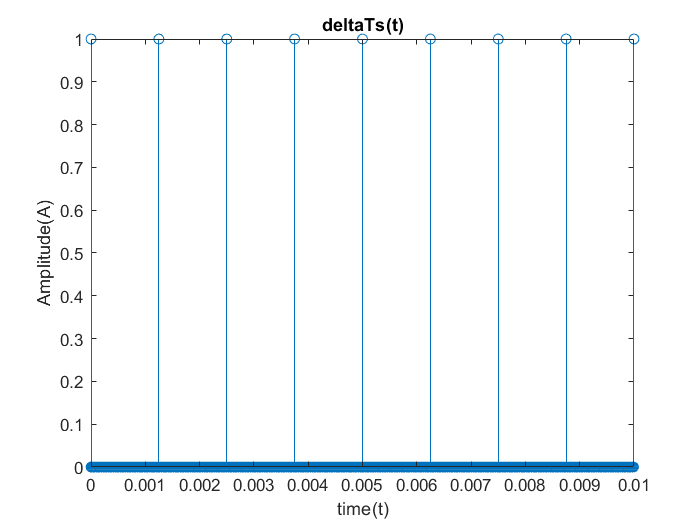

fnq=800;
fs=fnq;
Ts=1/fnq;
deltaTs=deltap(t,1/fs);
graph(t,deltaTs,"deltaTs(t)",false);

Then I'm multiplying the signal with impulse train to obtain the sampled signal.

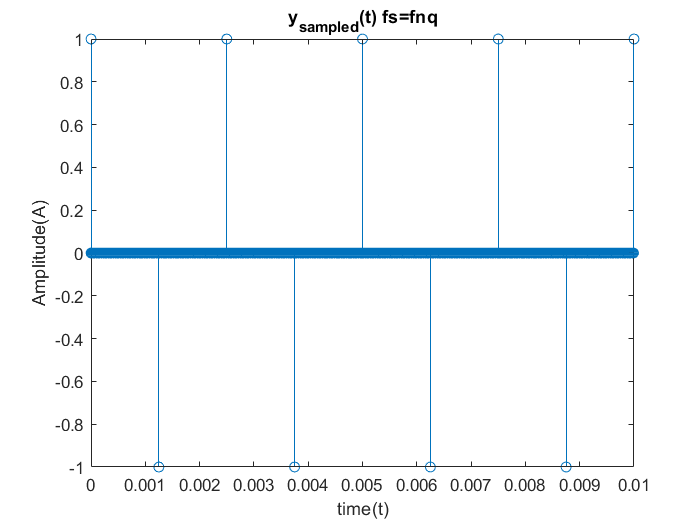

ydash=y.*deltaTs; %multiplying the signal with impulse train
graph(t,ydash,"y_{sampled}(t) fs=fnq",false);

Let's compare the sampled signal with the oroginal signal

I'm using a predefined function to compare original signal and sampled signal.

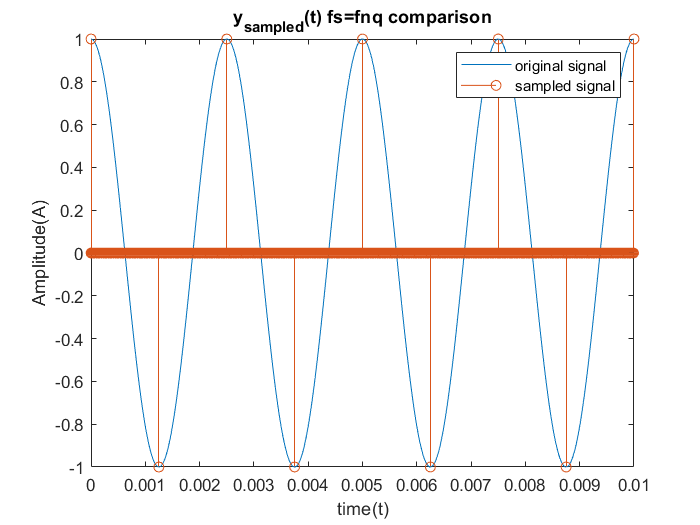

sampfig(t,ydash,y,"y_{sampled}(t) fs=fnq comparison")

**4. Sample and plot the signal at 2 times Nyquist rate (2fnq) and one-half of the Nyquist rate (fnq/2) along with the signal sampled at Nyquist rate (fnq) in the same plot. State your observations.**

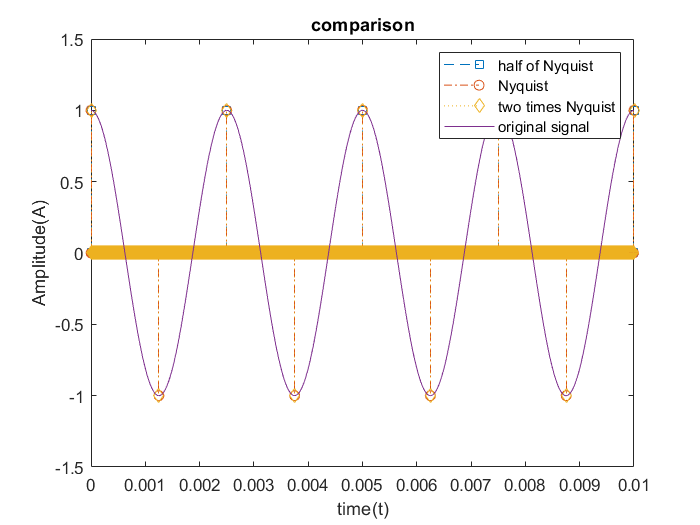

ydble=y.*deltap(t,1/(2*fnq));                       %creating an impulse train 
% with frequency of 2fnq and multiplying with the original signal
yhalf=y.*deltap(t,2/(fnq));                         %creating an impulse train with 
% frequency of fnq/2 and multiplying with the original signal

%plotting the results in the same graph
fig1=figure;
stem(t,yhalf,"--s")
hold on
stem(t,ydash,"-.")
stem(t,ydble,':d')
plot(t,y)
hold off
ylim([-1.5 1.5])
legend('half of Nyquist','Nyquist','two times Nyquist','original signal')
ylabel("Amplitude(A)");
xlabel("time(t)");
title('comparison');
saveas(fig1,"D:\ACA\Sem4\Analog and Digital Communication\assignment1\"+"comparison" + ...
    ""+".png")

We can't clearly see them apart from one another because they are overlapping. Let's plot them in same figure horizontally to get a clear understanding.

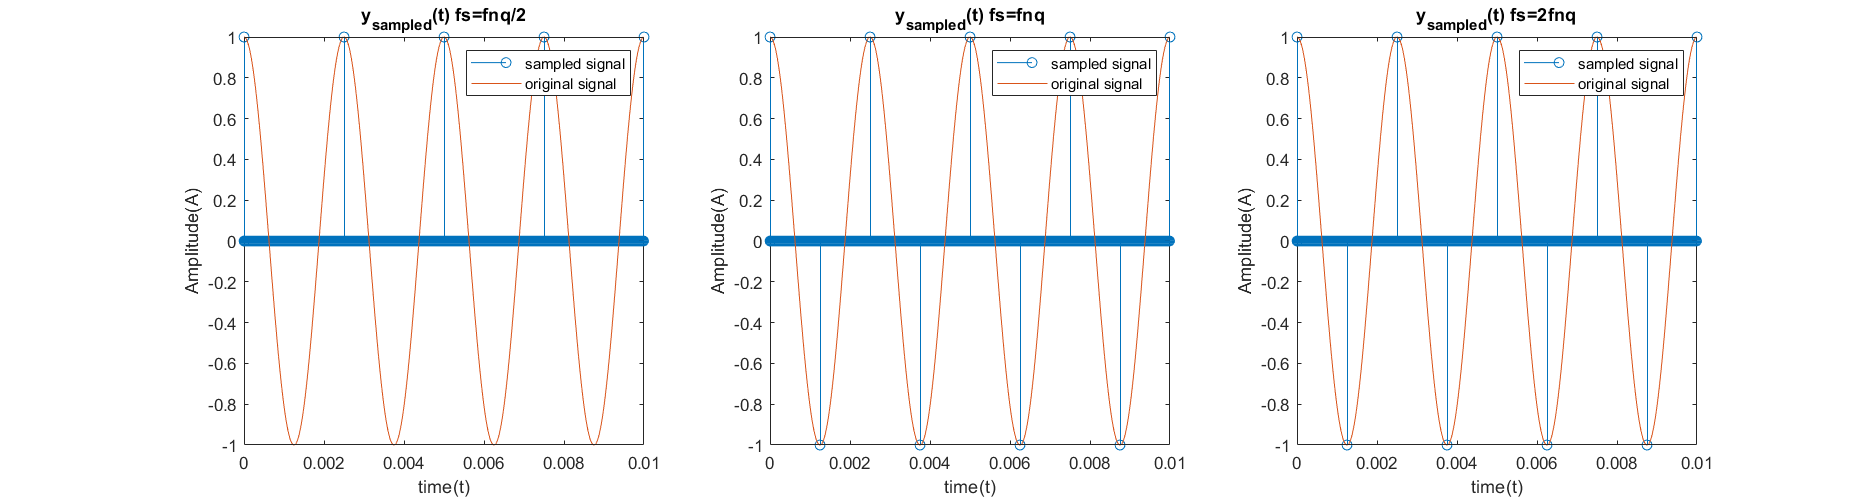

% plotting all in one figure
fig2=figure;
fig2.Position=[0 0 1500 400];
subplot(1,3,1);
stem(t,yhalf);
hold on
plot(t,y);
hold off
ylabel("Amplitude(A)");
xlabel("time(t)");
title("y_{sampled}(t) fs=fnq/2");
legend("sampled signal","original signal");

subplot(1,3,2);
stem(t,ydash);
hold on
plot(t,y);
hold off
ylabel("Amplitude(A)");
xlabel("time(t)");
title("y_{sampled}(t) fs=fnq");
legend("sampled signal","original signal");

subplot(1,3,3);
stem(t,ydble);
hold on
plot(t,y);
hold off
ylabel("Amplitude(A)");
xlabel("time(t)");
title("y_{sampled}(t) fs=2fnq");
legend("sampled signal","original signal");
saveas(fig2,"D:\ACA\Sem4\Analog and Digital Communication\assignment1\"+"sampling" + ...
    " comparison"+".png");

When sampling at half of the Nyquist frequency, some important peaks are missing. So it is impossible to reconstruct the original signal from the sampled signal.

As we can observe all important peaks are captured when sampled at two times of Nyquist frequency. But the graph doesn't show a difference from the signal sampled at the Nyquist frequency. Because the extra samples taken corresponds to zeros. So we can't visually see a difference.

By observing the above plots we can conclude that Nyquist frequency is the lowest frequency that we can use when sampling a signal in order to recover the original signal afterwards. If we reduce the sampling frequency lower than the Nyquist frequency, some of the most important information get lost. So some of the important data will not be transmitted. If we sample at a frequency higher than the Nyquist frequency, we can have enough samples to reconstruct the original signal at the reciever with minimum amount of noise.

So we can conclude that, Nyquist frequency is a good margin to use when choosing a sampling frequency.

**5. It is required to have a SNqR ratio greater than 25dB. What is the minimum number of bits (nb) required per a sample and number of minimum quantization levels (L) required?**

$\mathrm{SNqR}=\frac{3L^2 \ldotp \overline{g^2 \left(t\right)} }{{\mathrm{mp}}^2 }$, where

- L=Number of quantization levels

- mp=maximum aplitude of the original signal

- $\overline{g^2 \left(t\right)}$=average power of the original signal

Our signal is,


$$y\left(t\right)=A\ldotp \mathrm{cos}\left(2\pi \times f\times t\right)$$


So,


$$\mathrm{mp}=A=1$$


Since our signal is single cosine  component,


$$\bar{g^2 \left(t\right)} =\frac{A^2 }{2}$$



$$\bar{g^2 \left(t\right)} =\frac{1}{2}$$



$$\textrm{SNqR}=\frac{3L^2 }{2}$$


But SNqR should be greater than or equal to 25dB,


$$10{\mathrm{log}}_{10} \left(\mathrm{SNqR}\right)\ge 25$$



$${\mathrm{log}}_{10} \left(\mathrm{SNqR}\right)\ge \frac{5}{2}$$



$$\log_{10} \left(\frac{3L^2 }{2}\right)\ge \frac{5}{2}$$


So the minimum requirement,


$$\log_{10} \left(\frac{3{L_{\mathrm{min}} }^2 }{2}\right)=\frac{5}{2}$$



$$\frac{3{L_{\mathrm{min}} }^2 }{2}={10}^{\frac{5}{2}}$$



$${L_{\mathrm{min}} }^2 ={\frac{2}{3}10}^{\frac{5}{2}}$$



$$L_{\mathrm{min}} =\sqrt{{\frac{2}{3}\ldotp 10}^{\frac{5}{2}} }$$


Lmin=sqrt((2/3)*10^2.5)

Lmin = 14.5196

Since we are digitally encoding the quantized signal, encoding process becomes easy if we use a number of quantization levels(L) that is a power of 2. So we can choose 16 as the minimum number of quantization levels.


$$16=2^{\mathrm{nb}}$$



$$\mathrm{nb}=4$$


So it requires 4 bits to encode the transmitting signal.

**6. Quantization output values are chosen to be the middle value in the relevant zone (figure 2). Write a matlab function to take a sampled value, number of quantization levels (L) and range (maximum amplitude) and to output the quantized value.**

I have defined the function for this process in the functions section. Let's take a look at the function.

**quanticed_value=quantval(val,L,mp)**

Parameters,

- val: Actual value that needs be quanticed.

- L:    Number of quantization levels.

- mp: Maximum amplitude of the original signal.

Let's test the code with the given example in the assignment,

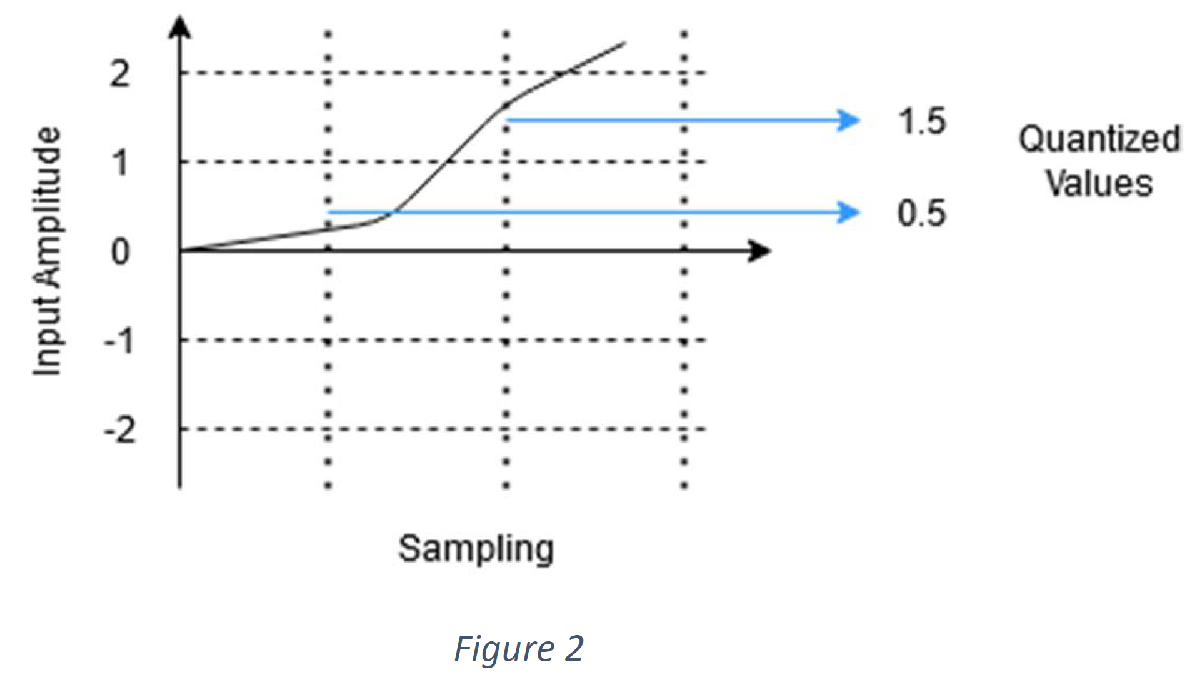

So, according to the example,


$$\mathrm{mp}=2$$



$$L=5$$


Let's test with an intermediate value 0.3,


$$\mathrm{val}=0\ldotp 3$$


So the output should be 0.5,

$\mathrm{quantized}\;\mathrm{value}$=0.5

quanticed_value=quantval(0.3,5,2)

quanticed_value = 0.5000

An ambiguity arises when an marginal value is given. For an example, if we want the quantized value of 1, then there are two possible regions. So I'm using the upper region as default to my function, except to the upper bound of the quantization levels.

So if we input 1, it should output 1.5

quanticed_value=quantval(1,5,2)

quanticed_value = 1.5000

If we input -2, it should output -1.5

quanticed_value=quantval(-2,5,2)

quanticed_value = -1.5000

Finally if we input the upperbound 2, it should output 1.5

quanticed_value=quantval(2,5,2)

quanticed_value = 1.5000

**7. Sample the signal at 8 times Nyquist sampling frequency (8fnq) and quantize it using above created function.**

Here I'm redefining the time axis, to match the high sampling frequency.

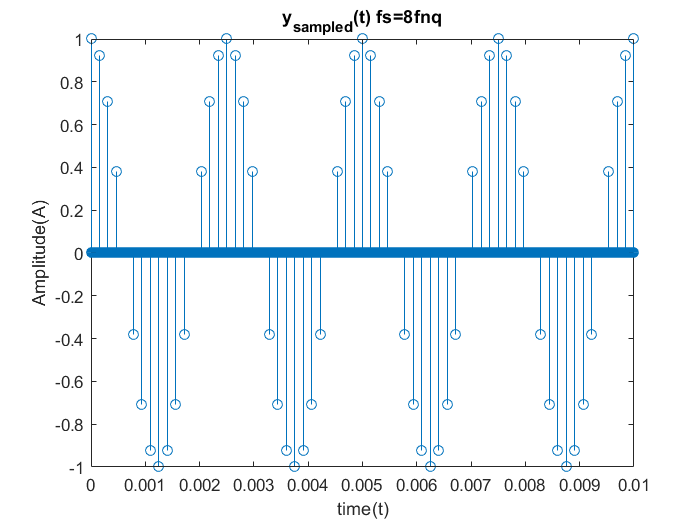

t=0:1e-8:0.01;                             %defining the time axis
y=cos(2*pi*f*t);                           %recreating the y(t) vector according to 
% the new time axis
yocta=y.*deltap(t,1/(8*fnq));              %creating the sampled function
graph(t,yocta,"y_{sampled}(t) fs=8fnq",false); %plotting the sampled function

Since the function I defined to get quantized values only works for single values, to quantize a whole vector, function **quantval(val,L,mp)** must be run for every value in the vector, through a loop. For this purpose I have predefined the function **quantice(y,L,mp)**

**quantice(y,L,mp)**

Parameters,

- y:    sampled signal vector.

- L:    Number of quantization levels.

- mp: Maximum amplitude of the original signal.

Let's quantize the sampled signal using L=16,

Here I'm using the predefined function **quanfig(t,yquant,y,name)** to plot quantized signals, with its' original signal

Parameters,

- t:           time axis vector

- yquant: quantized signal vector

- y:          original signal vector

- name:   title of the figure

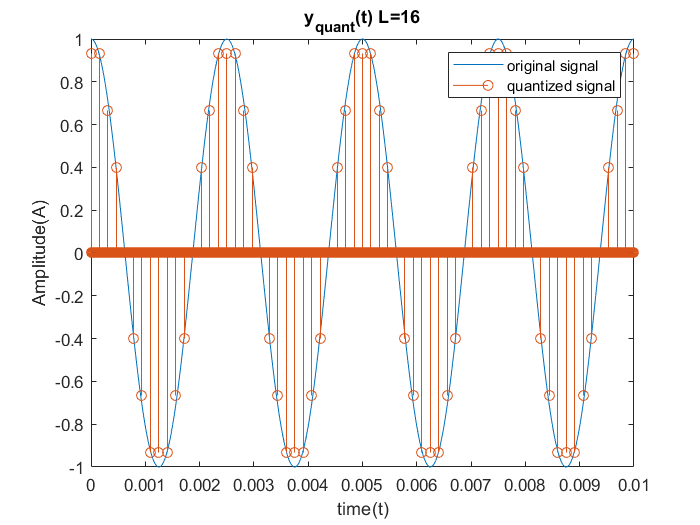

yquant=quantice(yocta,16,1); %quantizing the sampled signal    
quanfig(t,yquant,y,"y_{quant}(t) L=16") %plotting the quantized signal

**8. Quantize the sampled signal in 7 for L*2 and L/2 quantization levels. Plot the graphs and state your observations.**

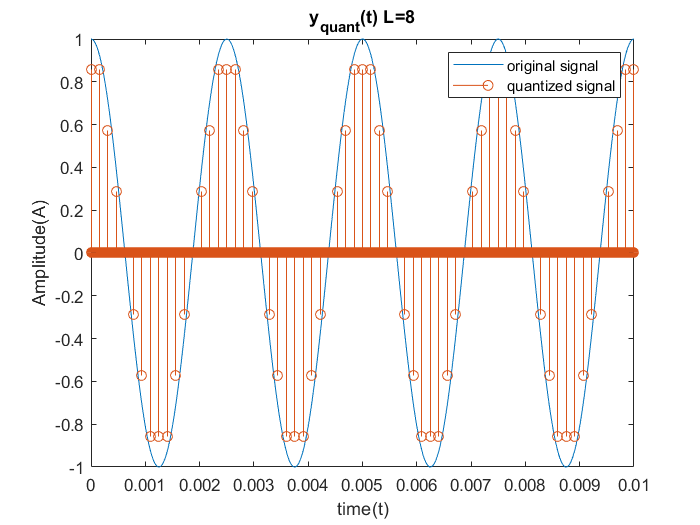

yquanthalf=quantice(yocta,8,1);
quanfig(t,yquanthalf,y,"y_{quant}(t) L=8")

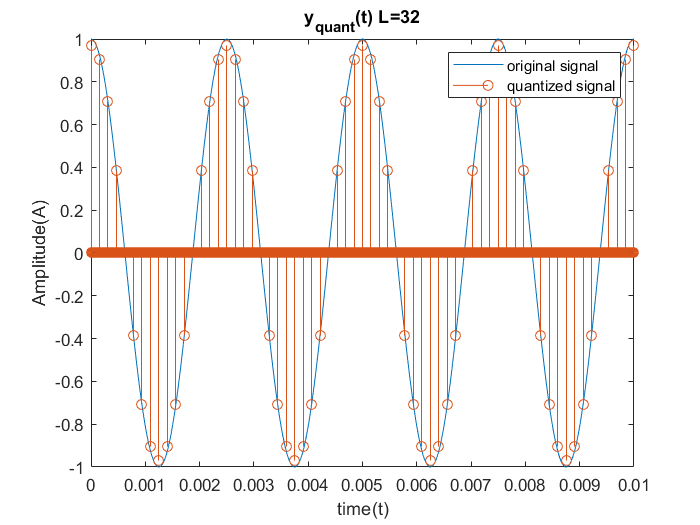

yquantdouble=quantice(yocta,32,1);
quanfig(t,yquantdouble,y,"y_{quant}(t) L=32")

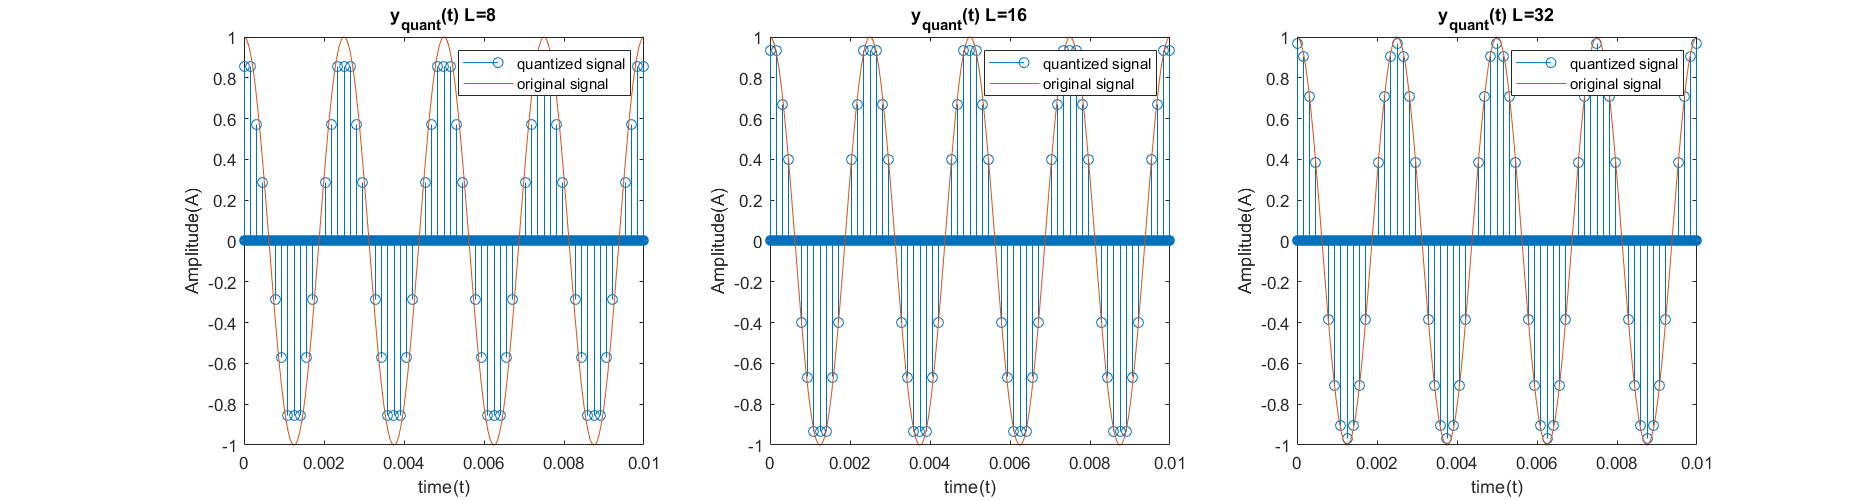

% plotting all in one figure for comparison
fig3=figure;
fig3.Position=[0 0 1500 400];
subplot(1,3,1);
stem(t,yquanthalf);
hold on
plot(t,y);
hold off
ylabel("Amplitude(A)");
xlabel("time(t)");
title("y_{quant}(t) L=8");
legend("quantized signal","original signal");

subplot(1,3,2);
stem(t,yquant);
hold on
plot(t,y);
hold off
ylabel("Amplitude(A)");
xlabel("time(t)");
title("y_{quant}(t) L=16");
legend("quantized signal","original signal");

subplot(1,3,3);
stem(t,yquantdouble);
hold on
plot(t,y);
hold off
ylabel("Amplitude(A)");
xlabel("time(t)");
title("y_{quant}(t) L=32");
legend("quantized signal","original signal");
saveas(fig3,"D:\ACA\Sem4\Analog and Digital Communication\assignment1\"+"quantization" + ...
    " comparison"+".png");

We can clearly observe that when the number of quantization level is below the minimum L that fulfills $25\mathrm{dB}\ge \mathrm{SNqR}$ some important infromation have lost. For an example take the signal quantized using $L=8$. Peaks of the oroginal signal is compressed to a lower value, which makes it harder to recover the original signal at the reciever. 

And when we look at the signal quantized using $L=32>L_{\mathrm{min}}$, we can observe that all the important information are preserved.

So we can conclude that 25dB margin is a good margin to avoid quantization noise.

out=qnvl(2,5,2)

out = 1.5000

## Functions

1.Function below creates an impulse response when the time axis array and the period is given. It outputs the vector of the impulse response function.

function deltaTs=deltap(t,Ts) %function to create impulse trains
deltaTs=zeros(size(t));
ts=t(end)/(length(t)-1);
deltaTs(1:Ts/ts:end)=1;
end

2.Function below outputs the quantized value, when the original value is given, with the number of quantization levels L and the maximum magnitude of the original signal mp.

%function to output quantized value when the original value is given
function out=quantval(val,L,mp)
levels=-mp:(2*mp)/(L-1):mp;
levels=[levels val];
levels=sort(levels);
indx=find(levels==val);
if (indx(end)==length(levels))
    out=(levels(indx(1)-1)+levels(indx(1)+1))/2;
else
    out=(levels(indx(end)-1)+levels(indx(end)+1))/2;
end
end

3.Function Below quantizes vectors using the function quantval(val,L,mp)

%function to quantize vectors using the quantval(val,L,mp) function
function yqnt=quantice(y,L,mp)
yqnt=zeros(size(y));
for i=1:length(y)
    yqnt(i)=quantval(y(i),L,mp);
end
end

4. Plotting functions

%function to plot continuous and discrete graphs
function graphs=graph(t,y,name,c)
    fig=figure;
    if c
       plot(t,y);
    else
       stem(t,y);
    end
    ylabel("Amplitude(A)");
    xlabel("time(t)");
    title(name);
    saveas(fig,"D:\ACA\Sem4\Analog and Digital Communication\assignment1\"+name+".png")
    graphs=true;
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%function to plot quantized signals with their original signals
function quanfig(t,yquant,y,name)
fig=figure;
plot(t,y);
hold on
stem(t,yquant);
hold off
ylabel("Amplitude(A)");
xlabel("time(t)");
title(name);
legend("original signal","quantized signal")
saveas(fig,"D:\ACA\Sem4\Analog and Digital Communication\assignment1\"+name+".png");
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%function to plot sampled signals with their original signals
function sampfig(t,ysamp,y,name)
fig=figure;
plot(t,y);
hold on
stem(t,ysamp);
hold off
ylabel("Amplitude(A)");
xlabel("time(t)");
title(name);
legend("original signal","sampled signal")
saveas(fig,"D:\ACA\Sem4\Analog and Digital Communication\assignment1\"+name+".png");
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function out=qnvl(val,L,mp)
levels=-mp:(2*mp)/(L-1):mp;
for i=levels
    if i>val
        break
    end
    temp=i;
end
if i==temp
    out=(i+levels(length(levels)-1))/2;
else
    out=(temp+i)/2;
end
end